# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0014;
c4 = 0.0077;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x  = 5;
x0 = 7.5;
x1 = 10;

**Target Shape **`h_target`

target = 0.1*ones(size(X));
target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

Boarder

[~,~,~,~,H_2,~,conds_Sol_2,...
    ~,~,output_2,history_2,History_2,h_Sol_2,H_Sol_2,OUTS_2]...
    = Solution(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          87.5431         
     1            4          83.8931         initial simplex
     2            5          83.8931         reflect
     3            7          75.9336         expand
     4            8          75.9336         reflect
     5           10          67.7105         expand
     6           12          52.7948         expand
     7           13          52.7948         reflect
     8           15          32.4376         expand
     9           16          32.4376         reflect
    10           18          30.7771         reflect
    11           20          22.2348         reflect
    12           22          22.0479         reflect
    13           24          22.0479         contract inside
    14           26          18.8261         reflect
    15           28          18.8261         contract outside
    16           29          18.8261         reflect
    17           31         


[~,~,~,~,H_2Possition,~,conds_Sol_2Possition,...
    ~,~,output_2Possition,history_2Possition,History_2Possition,h_Sol_2Possition,H_Sol_2Possition,OUTS_2Possition]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          87.5431         
     1            2          87.5431         initial simplex
     2            4          79.8111         expand
     3            6           66.593         expand
     4            8          40.2632         expand
     5           10          33.4929         reflect
     6           12          33.4929         contract inside
     7           15          33.4929         shrink
     8           18          33.4929         shrink
     9           21          33.4929         shrink
    10           23          33.4929         contract inside
    11           25          33.4929         contract inside
    12           27          33.4929         contract inside
    13           29          33.4928         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.To


[~,~,~,~,H_2Disjoining,myObjective_2Disjoining,conds_Sol_2Disjoining,...
    ~,~,output_2Disjoining,history_2Disjoining,History_2Disjoining,h_Sol_2Disjoining,H_Sol_2Disjoining,OUTS_2Disjoining]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_2Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          33.4928         
     1            3          32.6893         initial simplex
     2            5          19.4028         expand
     3            7           9.3918         expand
     4            8           9.3918         reflect
     5           10           9.3918         contract outside
     6           12           9.3918         contract outside
     7           14          8.64239         contract inside
     8           16          8.54938         reflect
     9           20          8.54938         shrink
    10           24          8.54938         shrink
    11           26          8.54938         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 7.580652 seconds.



[tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol,OUTS]...
    = Solution(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          105.967         
     1            4          105.119         initial simplex
     2            6          102.231         expand
     3            8          95.4022         expand
     4           10          91.1817         expand
     5           12          81.5101         expand
     6           14          71.6415         expand
     7           15          71.6415         reflect
     8           16          71.6415         reflect
     9           18          71.6415         contract outside
    10           19          71.6415         reflect
    11           21          71.6415         contract inside
    12           23          71.6415         contract inside
    13           25          65.8407         expand
    14           27          61.7309         expand
    15           29          50.0768         expand
    16           31           11.691         expand
    17           32      


[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition,OUTS_Possition]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          105.967         
     1            2          105.967         initial simplex
     2            4          102.393         expand
     3            6          90.9769         expand
     4            8          52.4982         expand
     5           10          36.7803         reflect
     6           12          36.7803         contract inside
     7           14          35.5572         contract inside
     8           16          35.5572         contract inside
     9           18          35.5572         contract inside
    10           20          35.5571         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 18.758356 seconds.



[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining,OUTS_Disjoining]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          35.5571         
     1            3          32.0296         initial simplex
     2            5          16.9468         expand
     3            7            5.787         expand
     4            8            5.787         reflect
     5           10            5.787         contract outside
     6           12          5.71618         contract outside
     7           14           3.9042         contract inside
     8           16           2.8992         reflect
     9           18           2.8992         contract inside
    10           22          2.66193         shrink
    11           24          2.66193         contract outside
    12           26          2.66193         contract inside
    13           28          2.65466         reflect
    14           30          2.65466         contract inside
    15           32          2.65466         contract inside
 
Optimization terminated:
 th


[~,~,~,~,H_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1,OUTS_1]...
    = Solution(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          108.452         
     1            4          107.621         initial simplex
     2            6          105.766         expand
     3            7          105.766         reflect
     4            9          103.322         expand
     5           11          100.935         expand
     6           12          100.935         reflect
     7           14          85.3892         expand
     8           16          77.0241         expand
     9           17          77.0241         reflect
    10           19          77.0241         expand
    11           20          77.0241         reflect
    12           21          77.0241         reflect
    13           23          77.0241         contract inside
    14           25          77.0241         reflect
    15           27          77.0241         reflect
    16           32          77.0241         shrink
    17           34          77.0241    


[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition,OUTS_1Possition]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          108.452         
     1            2          108.452         initial simplex
     2            4          108.452         reflect
     3            7          108.452         shrink
     4            9          108.434         reflect
     5           12          108.434         shrink
     6           14          108.434         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 12.750305 seconds.



[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining,OUTS_1Disjoining]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_1Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          108.434         
     1            3          107.606         initial simplex
     2            5          105.065         expand
     3            7          101.634         expand
     4            9           93.813         expand
     5           11          81.8394         expand
     6           13          77.0241         expand
     7           14          77.0241         reflect
     8           16          77.0241         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.893168 seconds.


nDisjoin_2 = size(history_2Disjoining(2:end,:));
nDisjoin_2 = nDisjoin_2(1);

nPossition_2 = size(history_2Possition);
nPossition_2 = nPossition_2(1); 

history2_2 = ones(nDisjoin_2+nPossition_2,3);

history2_2(1:nPossition_2,2:3) = [c1 c2].*ones(size(history_2Possition));
history2_2(nPossition_2+1:end,2:3) = history_2Disjoining(2:end,:);

history2_2(1:nPossition_2,1) = history_2Possition;
history2_2(nPossition_2+1:end,1) = history_2Possition(end).*ones(size(History_2Disjoining(2:end)));

History2_2 = [History_2Possition;History_2Disjoining(2:end)];


nDisjoin = size(history_Disjoining(2:end,:));
nDisjoin = nDisjoin(1);

nPossition = size(history_Possition);
nPossition = nPossition(1); 

history1 = ones(nDisjoin+nPossition,3);

history1(1:nPossition,2:3) = [c1 c2].*ones(size(history_Possition));
history1(nPossition+1:end,2:3) = history_Disjoining(2:end,:);

history1(1:nPossition,1) = history_Possition;
history1(nPossition+1:end,1) = history_Possition(end).*ones(size(History_Disjoining(2:end)));

History1 = [History_Possition;History_Disjoining(2:end)];


nDisjoin_1 = size(history_1Disjoining(2:end,:));
nDisjoin_1 = nDisjoin_1(1);

nPossition_1 = size(history_1Possition);
nPossition_1 = nPossition_1(1); 

history1_1 = ones(nDisjoin_1+nPossition_1,3);

history1_1(1:nPossition_1,2:3) = [c1 c2].*ones(size(history_1Possition));
history1_1(nPossition_1+1:end,2:3) = history_1Disjoining(2:end,:);

history1_1(1:nPossition_1,1) = history_1Possition;
history1_1(nPossition_1+1:end,1) = history_1Possition(end).*ones(size(History_1Disjoining(2:end)));

History1_1 = [History_1Possition;History_1Disjoining(2:end)];

**Inside Figures**

Fig. 0

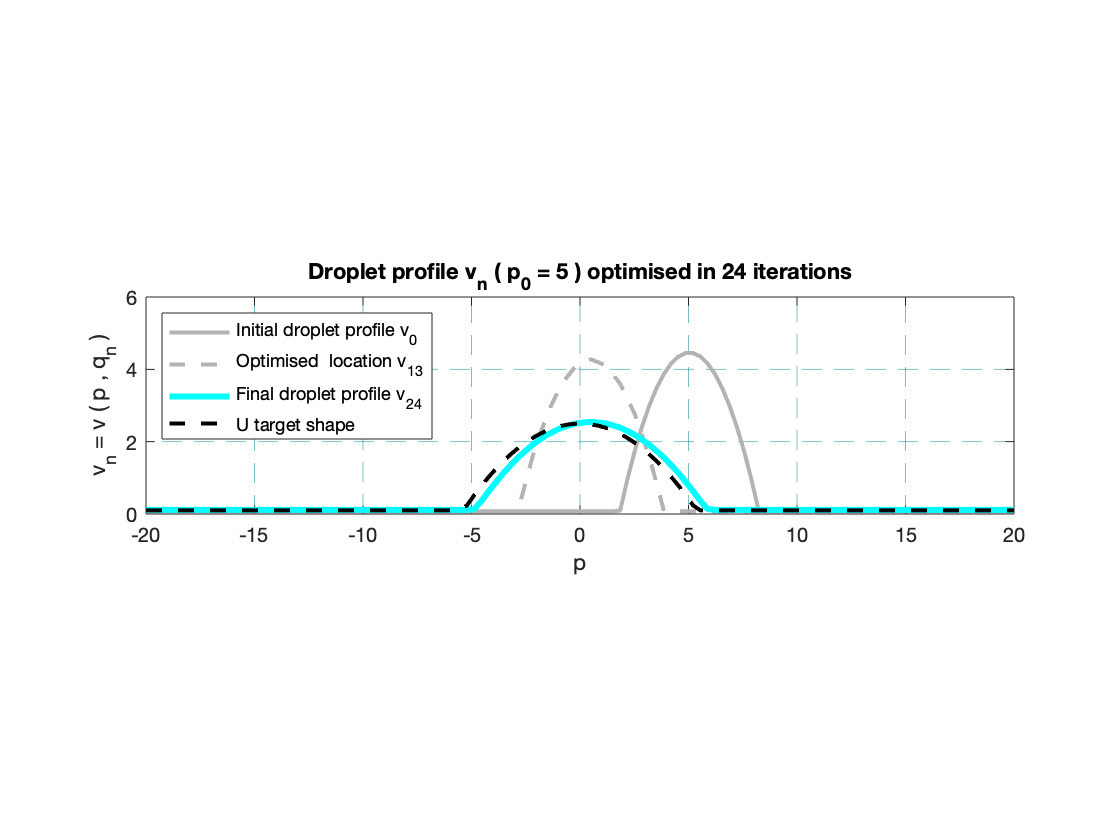

figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_2Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2Disjoining,'c-','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{13}',...
    'Final droplet profile v_{24}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 5 ) optimised in 24 iterations');
hold off

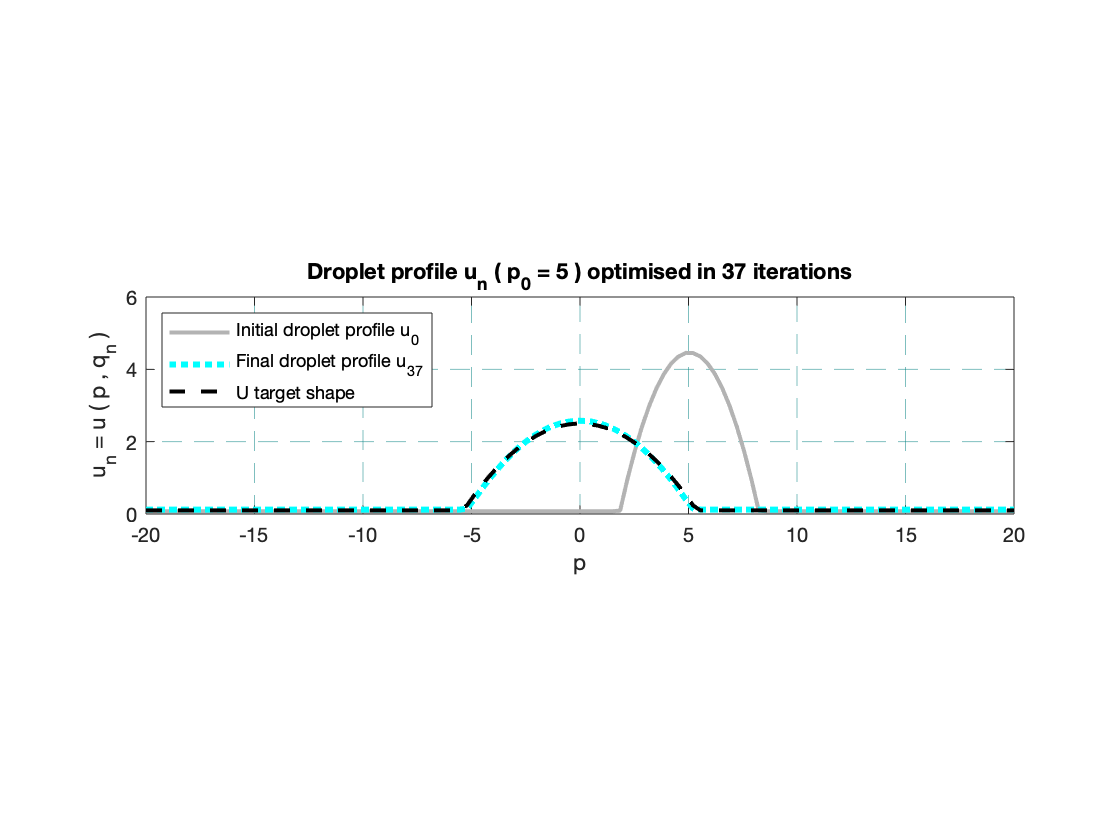


figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2,'c:','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{37}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 5 ) optimised in 37 iterations');
hold off

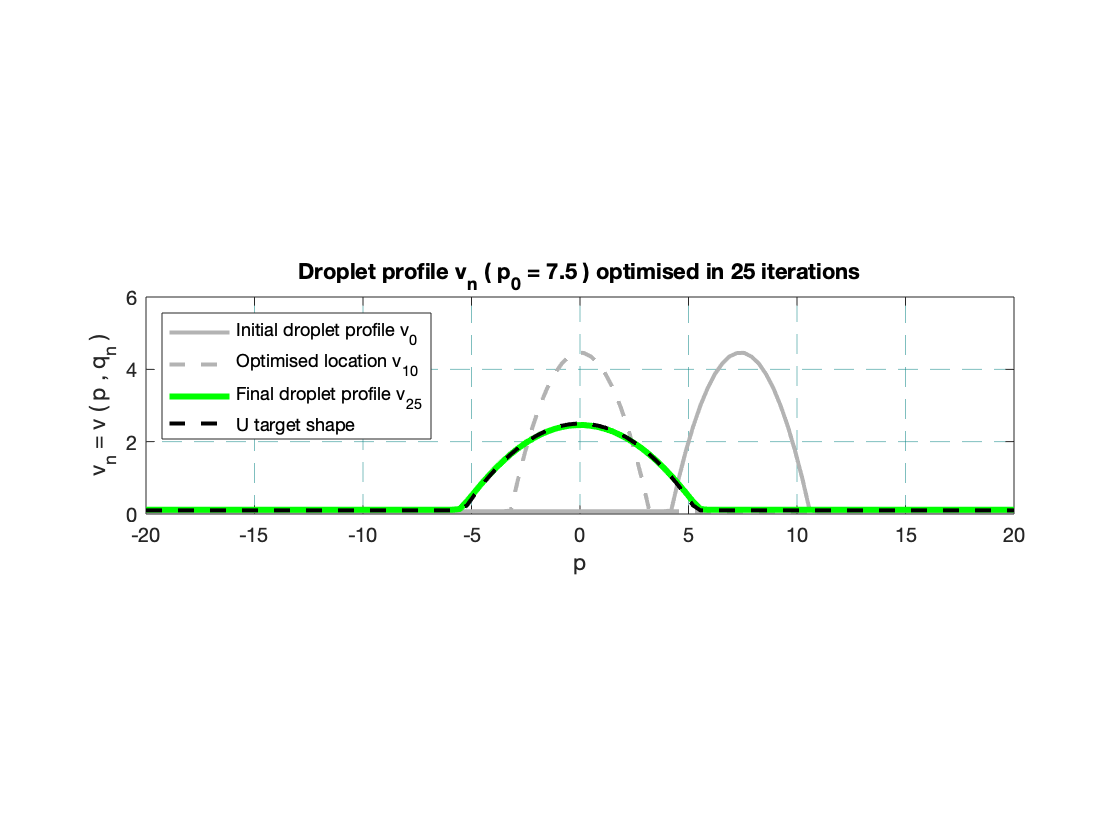


figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H0_Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_Disjoining,'g-','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised location v_{10}',...
    'Final droplet profile v_{25}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 7.5 ) optimised in 25 iterations');
hold off

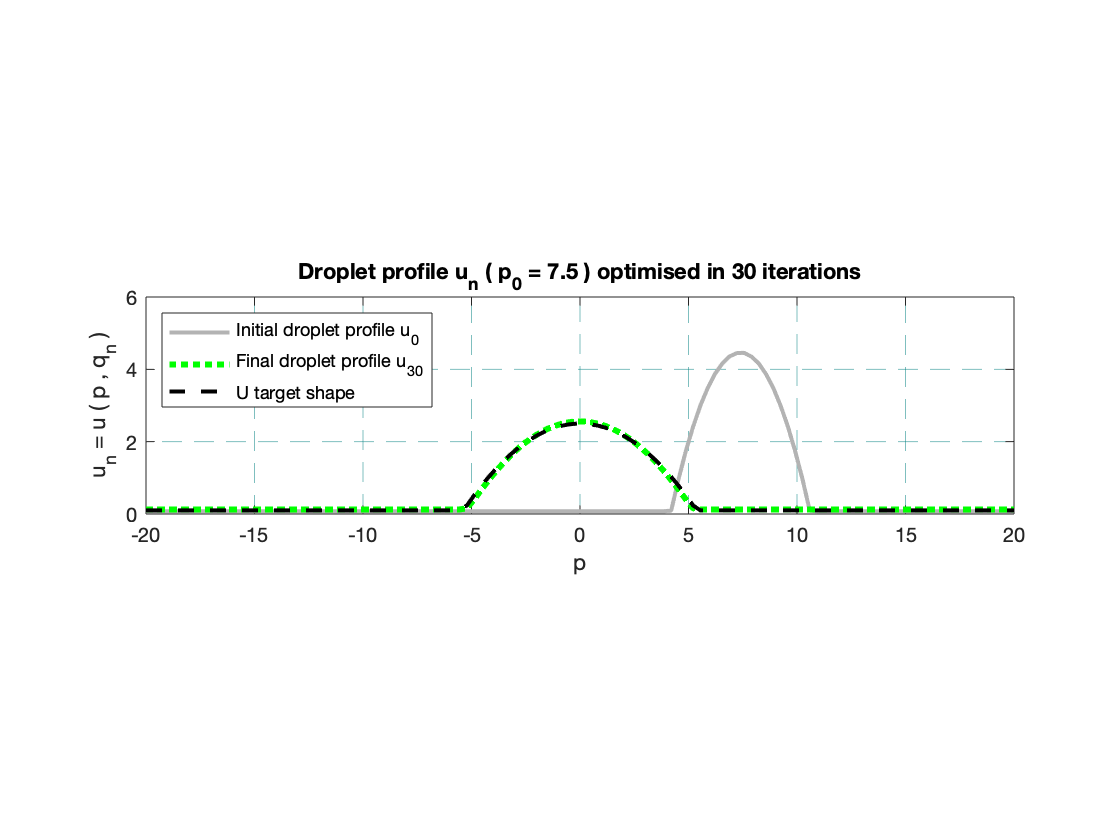


figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'g:','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{30}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 7.5 ) optimised in 30 iterations');
hold off

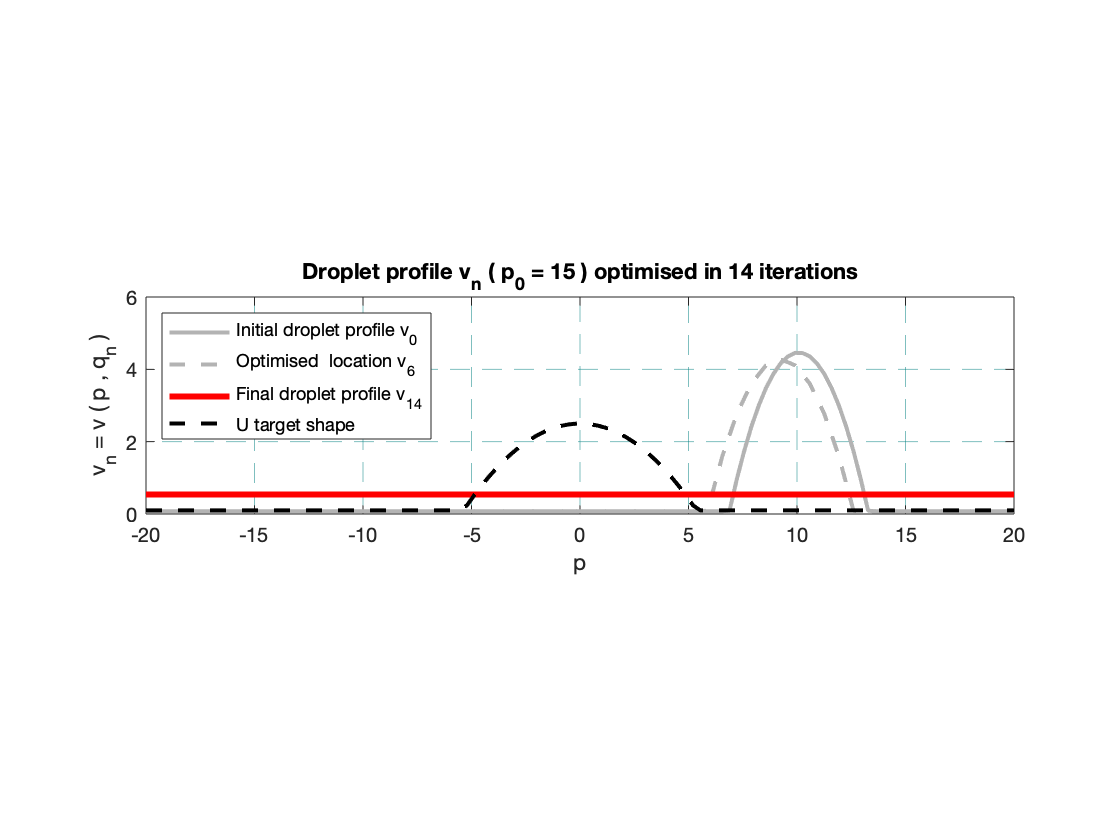


figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_1Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1Disjoining,'r-','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{6}',...
    'Final droplet profile v_{14}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 15 ) optimised in 14 iterations');
hold off

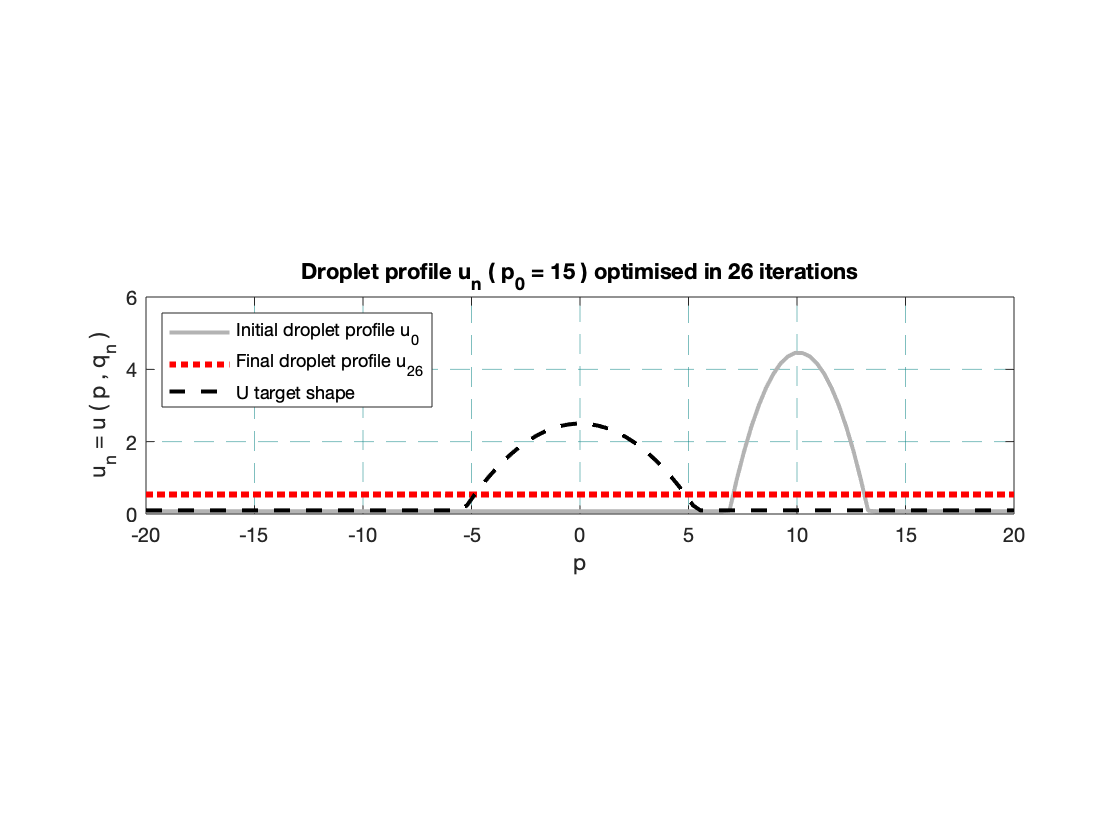


figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r:','linewidth',3);
plot(X,target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{26}',...
    'U target shape',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 15 ) optimised in 26 iterations');
hold off

**Joint Figures**

Fig. 1

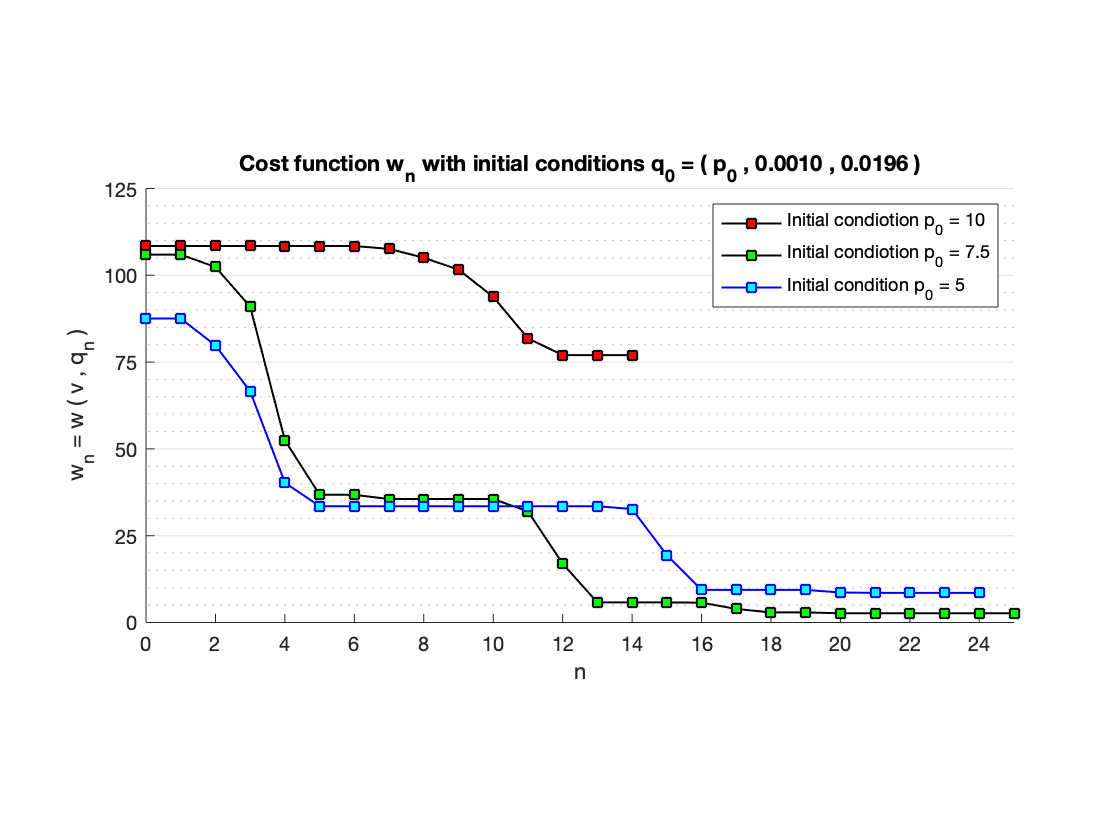

figure;
hold on
plot(0:14,History1_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:25,History1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,History2_2,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( v , q_n )');
xlabel('n');
legend('Initial condiotion p_0 = 10','Initial condiotion p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Cost function w_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 25]);
ylim([0 125]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

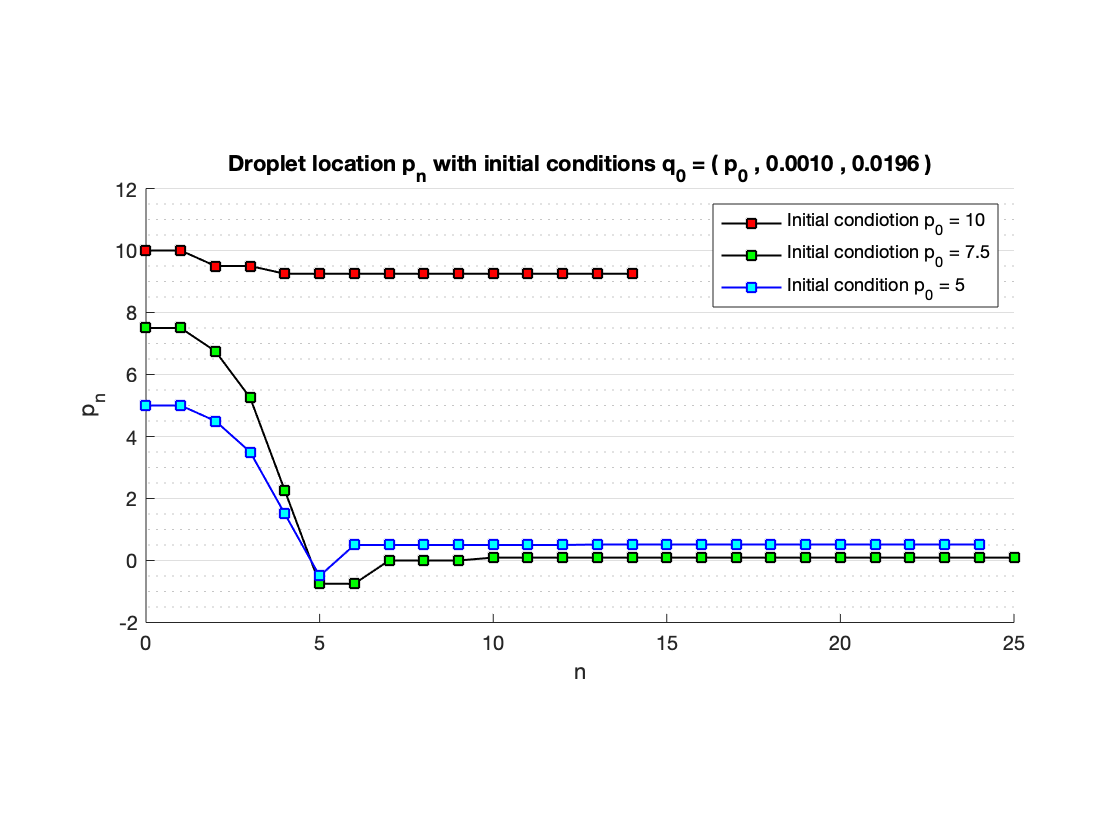


figure;
hold on
plot(0:14,history1_1(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:25,history1(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,history2_2(:,1),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condiotion p_0 = 10','Initial condiotion p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 25]);
ylim([-2 12]);
set(gca,'ytick',-4:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

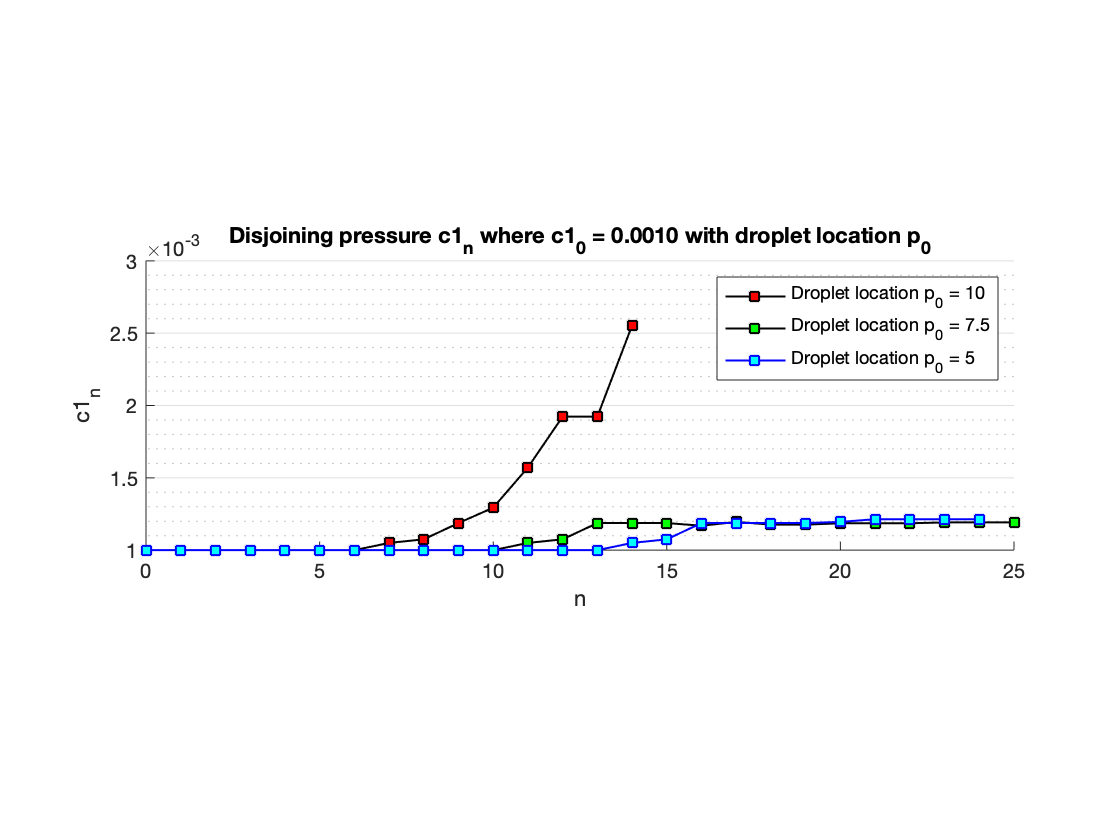


figure;
hold on
plot(0:14,history1_1(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:25,history1(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,history2_2(:,2),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with droplet location p_0');
legend('Droplet location p_0 = 10','Droplet location p_0 = 7.5','Droplet location p_0 = 5','Location','northeast');
xlim([0 25]);
ylim([.001 .003]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

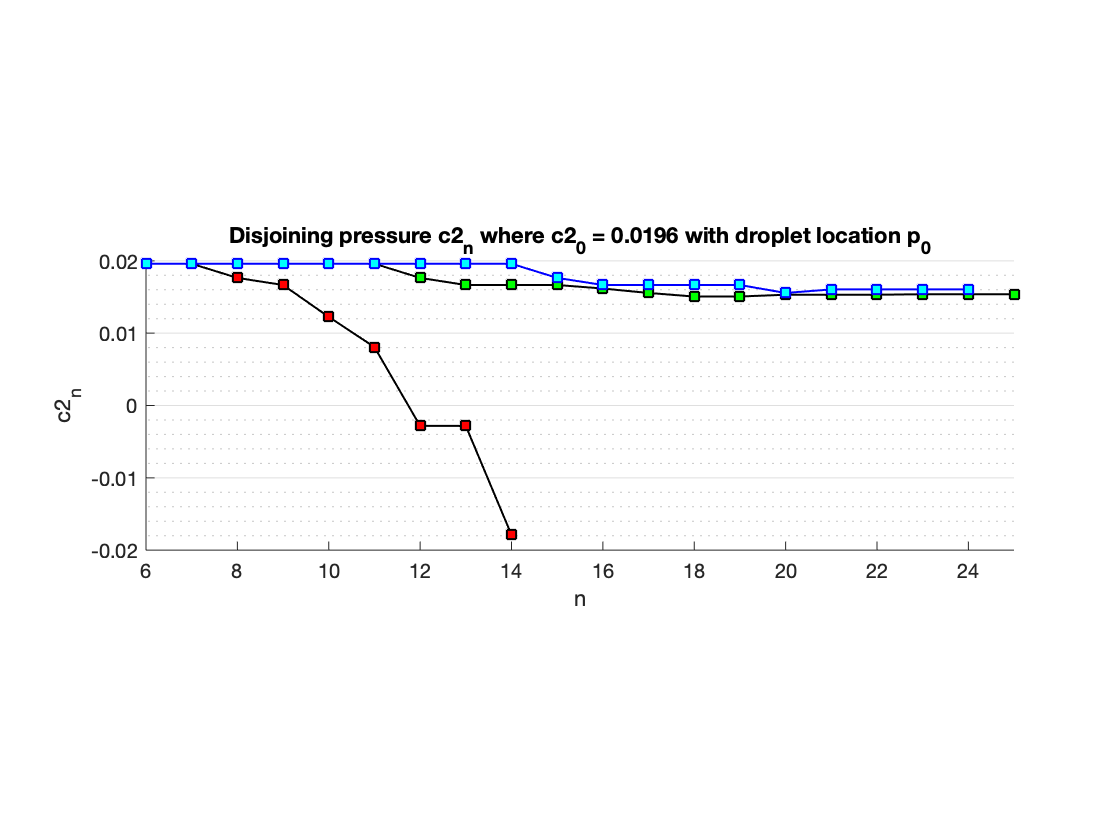


figure;
hold on
plot(0:14,history1_1(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:25,history1(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,history2_2(:,3),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with droplet location p_0');
xlim([6 25]);
ylim([-0.02 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

**Joint Figures**

Fig. 1

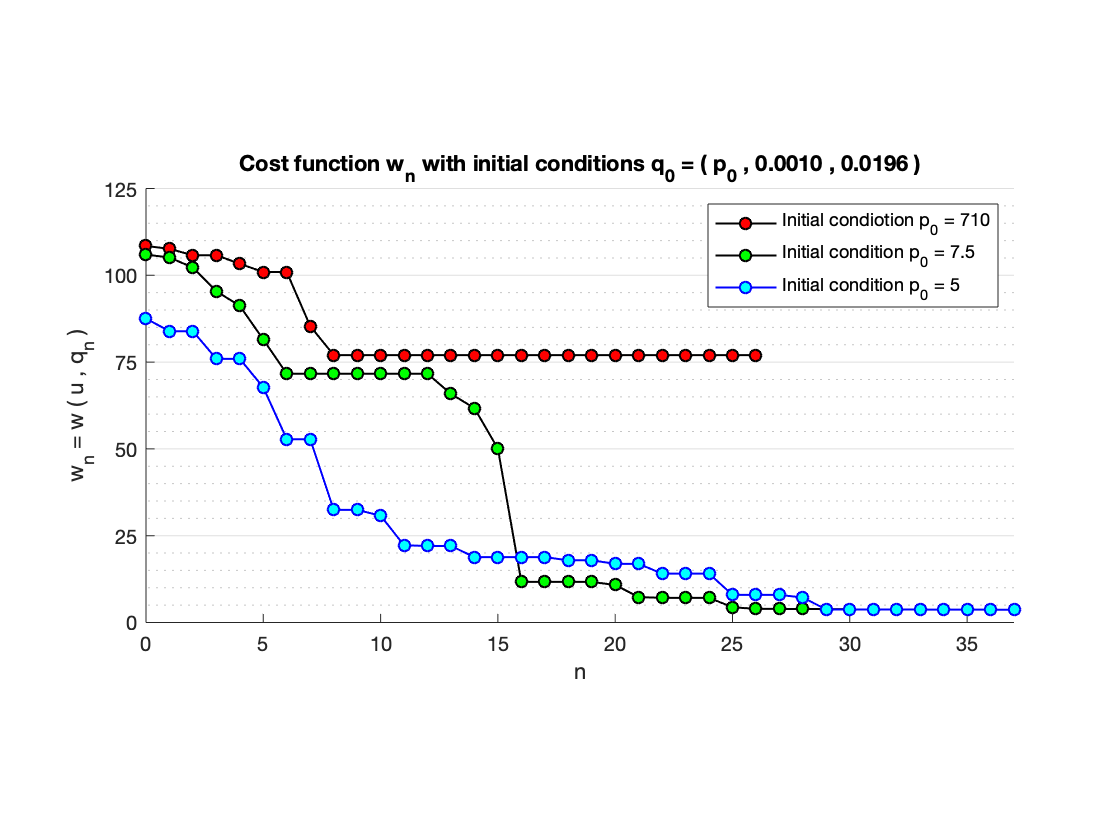

figure;
hold on
plot(0:26,History_1,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:30,History,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:37,History_2,'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condiotion p_0 = 710','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Cost function w_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 37]);
ylim([0 125]);
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

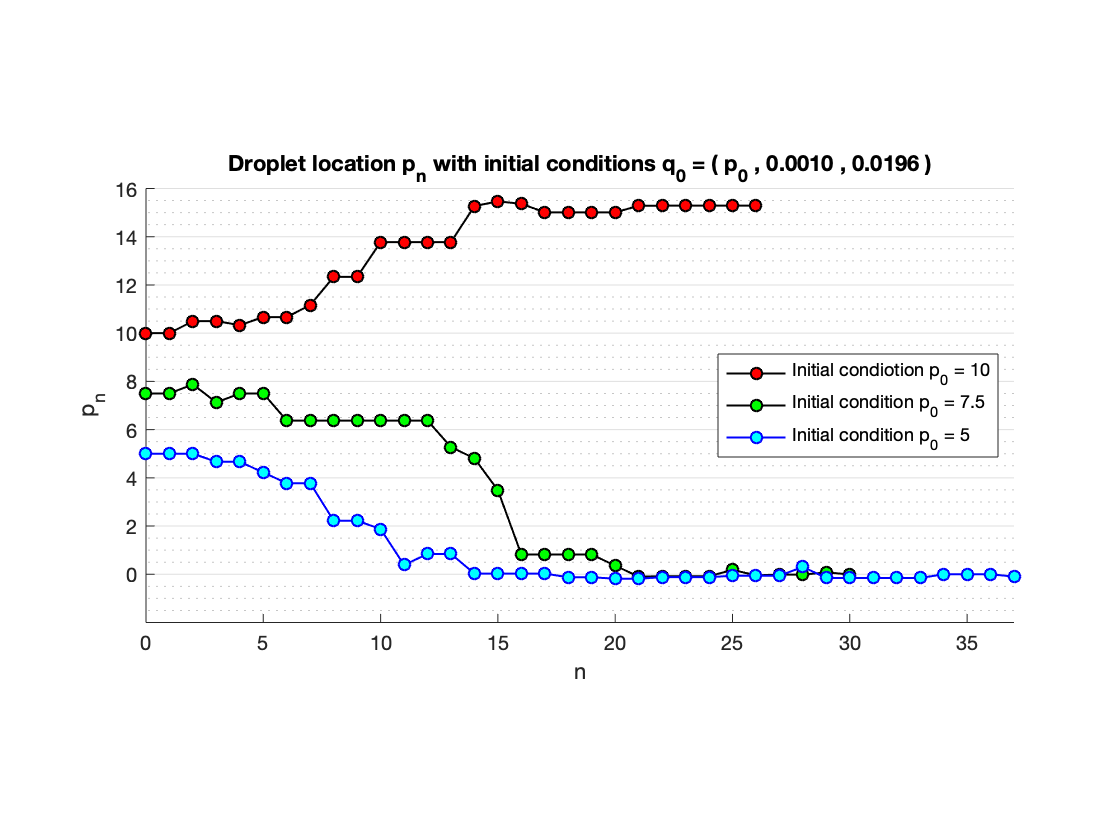


figure;
hold on
plot(0:26,history_1(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:30,history(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:37,history_2(1,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condiotion p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','east');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 37]);
ylim([-2 16]);
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

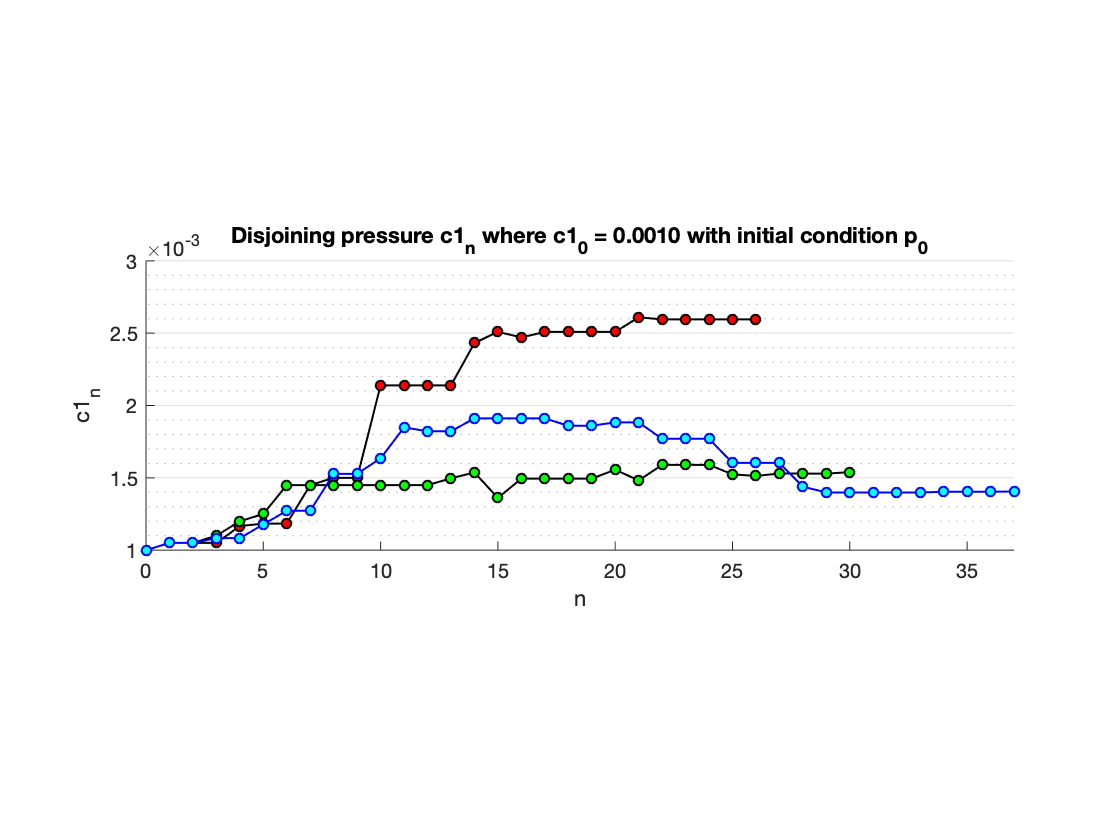


figure;
hold on
plot(0:26,history_1(2,:),'k-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:30,history(2,:),'k-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:37,history_2(2,:),'b-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with initial condition p_0');
%legend('Initial condiotion p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','best');
xlim([0 37]);
ylim([.001 .003]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

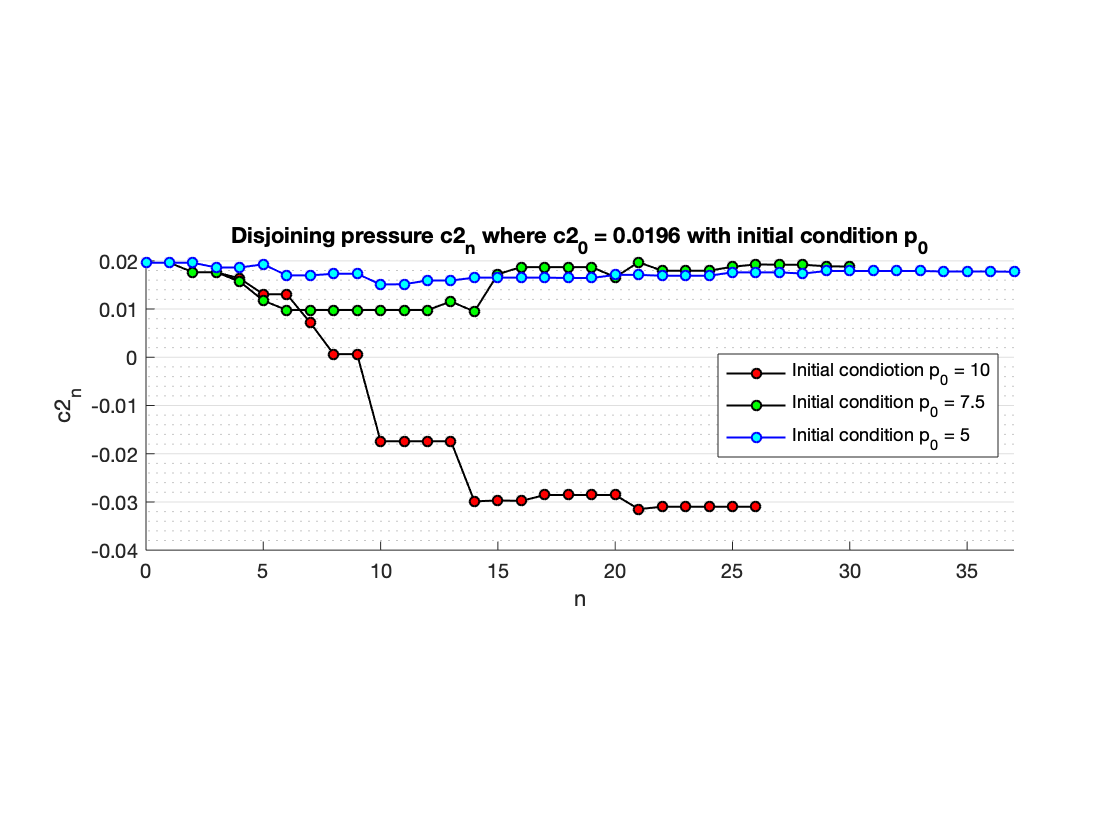


figure;
hold on
plot(0:26,history_1(3,:),'k-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:30,history(3,:),'k-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:37,history_2(3,:),'b-o',...
    'MarkerSize',5,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with initial condition p_0');
legend('Initial condiotion p_0 = 10','Initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','east');
set(gca,'xtick',0:5:100);
xlim([0 37]);
ylim([-.04 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

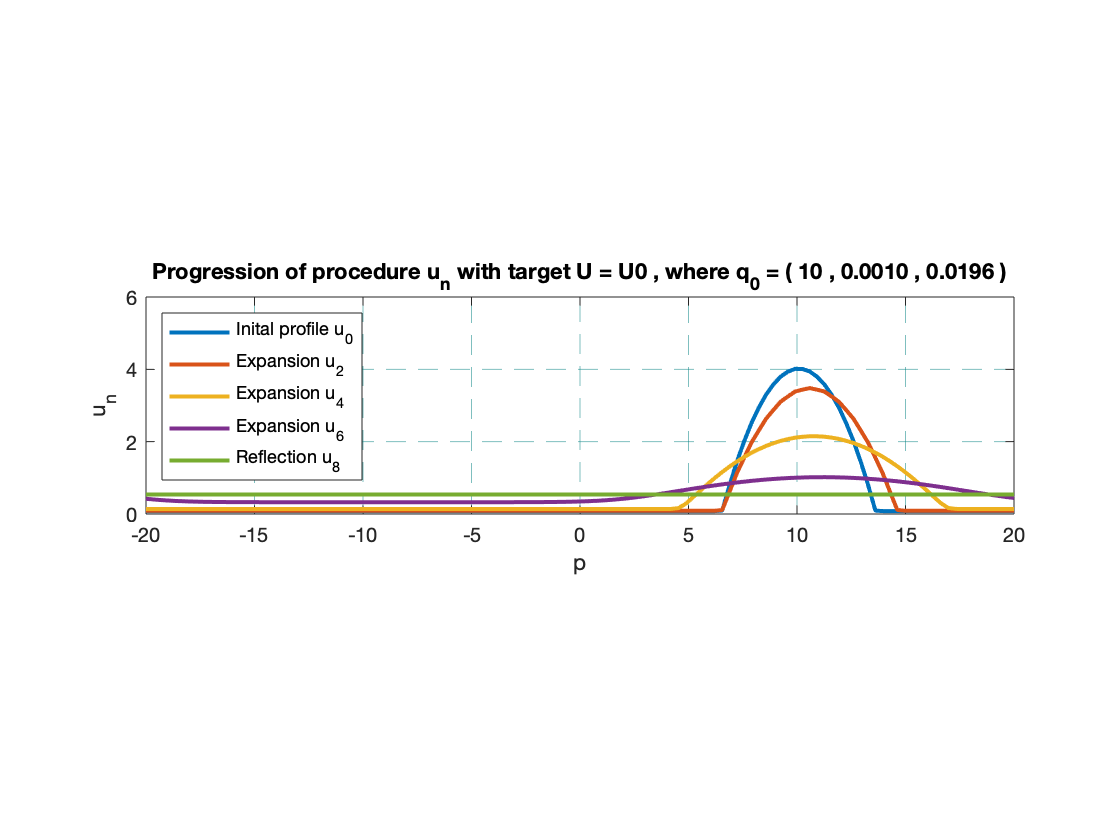

var = [A;N;k;y0]; 
% Set time span
tSpan = [1e-6 tfinal]; 
% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2);

% figure;
% hold on
% 
% for i = 0:9
%     hhh = hFinal([10+i;0.0010;0.0196],X,var,D1,D2,tSpan);
%     ht = deval(hhh,tfinal);
%     p = plot(X,ht);
%     drawnow
%     pause(0.1);
% end
% 
% pbaspect([2 1 1]);
% xlim([-20 20]);
% ylim([0 6]);
% xlabel('p');
% ylabel('u_n = u ( p , q_n )');
% grid on
% box on
% ax = gca;
% ax.GridColor = [0 .5 .5];
% ax.GridLineStyle = '--';
% ax.GridAlpha = 0.5;
% hold off

figure;
hold on

for i = 1:2:9
    hhh = hFinal(history_1(:,i+1),X,var,D1,D2,tSpan);
    ht = deval(hhh,tfinal);
    p = plot(X,ht,'linewidth',2);
    drawnow
    pause(0.1);
end

pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Inital profile u_0',...
    'Expansion u_2',...
    'Expansion u_4',...
    'Expansion u_6',...
    'Reflection u_8',...
    'Location','northwest');
title('Progression of procedure u_n with target U = U0 , where q_0 = ( 10 , 0.0010 , 0.0196 )');
hold off


T = struct2table(OUTS)

T = 31×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        105.97    {0×0 char          }
        1            4        105.12    {'initial simplex' }
        2            6        102.23    {'expand'          }
        3            8        95.402    {'expand'          }
        4           10        91.182    {'expand'          }
        5           12         81.51    {'expand'          }
        6           14        71.642    {'expand'          }
        7           15        71.642    {'reflect'         }
        8           16        71.642    {'reflect'         }
        9           18        71.642    {'contract outside'}
       10           19        71.642    {'reflect'         }
       11           21        71.642    {'contract insi

filename = 'T.xlsx';
writetable(T,filename,'Sheet',1,'Range','D1')
T_1 = struct2table(OUTS_1)

T_1 = 27×4 table
    iteration    funccount     fval          procedure     
    _________    _________    ______    ___________________

        0            1        108.45    {0×0 char         }
        1            4        107.62    {'initial simplex'}
        2            6        105.77    {'expand'         }
        3            7        105.77    {'reflect'        }
        4            9        103.32    {'expand'         }
        5           11        100.93    {'expand'         }
        6           12        100.93    {'reflect'        }
        7           14        85.389    {'expand'         }
        8           16        77.024    {'expand'         }
        9           17        77.024    {'reflect'        }
       10           19        77.024    {'expand'         }
       11           20        77.024    {'reflect'        }
      

filename = 'T_1.xlsx';
writetable(T_1,filename,'Sheet',1,'Range','D1')
T_2 = struct2table(OUTS_2)

T_2 = 38×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        87.543    {0×0 char          }
        1            4        83.893    {'initial simplex' }
        2            5        83.893    {'reflect'         }
        3            7        75.934    {'expand'          }
        4            8        75.934    {'reflect'         }
        5           10        67.711    {'expand'          }
        6           12        52.795    {'expand'          }
        7           13        52.795    {'reflect'         }
        8           15        32.438    {'expand'          }
        9           16        32.438    {'reflect'         }
       10           18        30.777    {'reflect'         }
       11           20        22.235    {'reflect'   

filename = 'T_2.xlsx';
writetable(T_2,filename,'Sheet',1,'Range','D1')



TP = struct2table(OUTS_Possition)

TP = 11×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        105.97    {0×0 char          }
        1            2        105.97    {'initial simplex' }
        2            4        102.39    {'expand'          }
        3            6        90.977    {'expand'          }
        4            8        52.498    {'expand'          }
        5           10         36.78    {'reflect'         }
        6           12         36.78    {'contract inside' }
        7           14        35.557    {'contract inside' }
        8           16        35.557    {'contract inside' }
        9           18        35.557    {'contract inside' }
       10           20        35.557    {'contract outside'}


filename = 'TP.xlsx';
writetable(TP,filename,'Sheet',1,'Range','D1')
T_1P = struct2table(OUTS_1Possition)

T_1P = 7×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        108.45    {0×0 char          }
        1            2        108.45    {'initial simplex' }
        2            4        108.45    {'reflect'         }
        3            7        108.45    {'shrink'          }
        4            9        108.43    {'reflect'         }
        5           12        108.43    {'shrink'          }
        6           14        108.43    {'contract outside'}


filename = 'T_1P.xlsx';
writetable(T_1P,filename,'Sheet',1,'Range','D1')
T_2P = struct2table(OUTS_2Possition)

T_2P = 14×4 table
    iteration    funccount     fval          procedure     
    _________    _________    ______    ___________________

        0            1        87.543    {0×0 char         }
        1            2        87.543    {'initial simplex'}
        2            4        79.811    {'expand'         }
        3            6        66.593    {'expand'         }
        4            8        40.263    {'expand'         }
        5           10        33.493    {'reflect'        }
        6           12        33.493    {'contract inside'}
        7           15        33.493    {'shrink'         }
        8           18        33.493    {'shrink'         }
        9           21        33.493    {'shrink'         }
       10           23        33.493    {'contract inside'}
       11           25        33.493    {'contract inside'}
     

filename = 'T_2P.xlsx';
writetable(T_2P,filename,'Sheet',1,'Range','D1')

TD = struct2table(OUTS_Disjoining)

TD = 16×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        35.557    {0×0 char          }
        1            3         32.03    {'initial simplex' }
        2            5        16.947    {'expand'          }
        3            7         5.787    {'expand'          }
        4            8         5.787    {'reflect'         }
        5           10         5.787    {'contract outside'}
        6           12        5.7162    {'contract outside'}
        7           14        3.9042    {'contract inside' }
        8           16        2.8992    {'reflect'         }
        9           18        2.8992    {'contract inside' }
       10           22        2.6619    {'shrink'          }
       11           24        2.6619    {'contract out

filename = 'TD.xlsx';
writetable(TD,filename,'Sheet',1,'Range','D1')
T_1D = struct2table(OUTS_1Disjoining)

T_1D = 9×4 table
    iteration    funccount     fval          procedure     
    _________    _________    ______    ___________________

        0            1        108.43    {0×0 char         }
        1            3        107.61    {'initial simplex'}
        2            5        105.06    {'expand'         }
        3            7        101.63    {'expand'         }
        4            9        93.813    {'expand'         }
        5           11        81.839    {'expand'         }
        6           13        77.024    {'expand'         }
        7           14        77.024    {'reflect'        }
        8           16        77.024    {'reflect'        }


filename = 'T_1D.xlsx';
writetable(T_1D,filename,'Sheet',1,'Range','D1')
T_2D = struct2table(OUTS_2Disjoining)

T_2D = 12×4 table
    iteration    funccount     fval          procedure      
    _________    _________    ______    ____________________

        0            1        33.493    {0×0 char          }
        1            3        32.689    {'initial simplex' }
        2            5        19.403    {'expand'          }
        3            7        9.3918    {'expand'          }
        4            8        9.3918    {'reflect'         }
        5           10        9.3918    {'contract outside'}
        6           12        9.3918    {'contract outside'}
        7           14        8.6424    {'contract inside' }
        8           16        8.5494    {'reflect'         }
        9           20        8.5494    {'shrink'          }
       10           24        8.5494    {'shrink'          }
       11           26        8.5494    {'contract o

filename = 'T_2D.xlsx';
writetable(T_2D,filename,'Sheet',1,'Range','D1')